# Load CSV Measurement Data

%Zu importierende Datei auswählen
filename = "DD6_X_500_1"

filename = "DD6_X_500_1"

%filename = "DC8/varTheta3DC8_1";
%Importieren und nicht relevante Informationen entfernen
data = readtable(filename);
data([1:17],:)=[];

taskTime = 10e-3; %10ms
angesteuerteRichtung="x"; %hier angeben welche Ricktung (x,y,theta) angesteurt wurde. Benoetigt, um unten automatisch cov() zu berechnen.

## Encoderdaten filtern

## Koordinatentransformation RoboterKS auf GlobalKS

vRobotKS = zeros(3,1);


xOdo = zeros(height(data),1);
yOdo = zeros(height(data),1);
thetaOdo = zeros(height(data),1);

for row = 1 : height(data)
    vRobotKS = [data{row, "vXFromMotor"}; data{row, "vYFromMotor"}; data{row, "vThetaFromMotor"}] ;
    if row > 1
        xOdo(row) = xOdo(row-1) + vRobotKS(1)*taskTime;
        yOdo(row) = yOdo(row-1) + vRobotKS(2)*taskTime;
        thetaOdo(row) = thetaOdo(row-1) + vRobotKS(3)*taskTime;
    end

    % Odometrie
end


## Plotten der Berechnungen

% Plot x-Koordinatenverlauf nach Odomterie, transformeirter Odo vs Kamera
distX=data(:,"distX")

distX = 1183×1 table
    distX
    _____

      0  
      0  
      0  
      0  
      0  
      0  
      0  
      0  
      0  
      0  
      0  
      0  
      0  
      0  
      0  
      0  


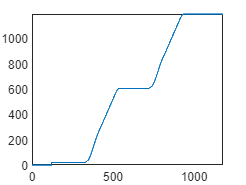

distX=table2array(distX);
%plot(distX); hold on;
plot(xOdo); hold on;
hold off;

%legend("distX","Odometrie xTf","Kamera x");
%legend("distX","xOdo");
%legend("xOdo");


## Umschaltpunkte ermitteln

% In diesem Abschnitt werden die Indizes ermittelt zu denen die
% ST-StateMachine ihren State verändert hat. In state 0 wartet der Robob 2
% sec nach statren des task mit dem losfahren. Bei State 1 wird dann die
% geschwindigkeit v=vsoll gesetzt und der Robo faehrt 2 sec. state 2 v=0
% fuer 2sec. state 3 v=vsoll fuer 2 sec. state 4 v=0.
stateOld=0;
state0to1 = 0;
state1to2 = 0;
state2to3 = 0;
state3to4 = 0;

for row = 1 : height(data)
    switch data{row, "state"}
        case 1
            if stateOld == 0
                state0to1 = row
            end
            stateOld = 1;
        case 2
            if stateOld == 1
                state1to2 = row
            end
            stateOld = 2;
        case 3
            if stateOld == 2
                state2to3 = row
            end
            stateOld = 3;
        case 4
            if stateOld == 3
                state3to4 = row
            end
            stateOld = 4;
        otherwise
    end
end

state0to1 = 320

state1to2 = 519

state2to3 = 718

state3to4 = 917

## Berechnen der zurueckgelegten Strecken je Ansteuerung

% In diesem Abschnitt wird anhand der zuvor berechneten Odometrie ermittelt
% welche Strecke der Robo zurueckgelegt hat und welche er haette
% zurücklegen sollen

xDiff0to2 = xOdo(state1to2) - xOdo(state0to1)

xDiff0to2 = 555.3078

yDiff0to2 = yOdo(state1to2) - yOdo(state0to1)

yDiff0to2 = 1.3908

thetaDiff0to2 = thetaOdo(state1to2) - thetaOdo(state0to1)

thetaDiff0to2 = 0.0037


xDiff2to4 = xOdo(height(data)-1) - xOdo(state2to3)

xDiff2to4 = 587.1246

yDiff2to4 = yOdo(height(data)-1) - yOdo(state2to3)

yDiff2to4 = 0.3707

thetaDiff2to4 = thetaOdo(height(data)-1) - thetaOdo(state2to3)

thetaDiff2to4 = 0.0021


xDiff0to4 = xDiff0to2 + xDiff2to4

xDiff0to4 = 1.1424e+03

yDiff0to4 = yDiff0to2 + yDiff2to4

yDiff0to4 = 1.7615

thetaDiff0to4 = thetaDiff0to2 + thetaDiff2to4

thetaDiff0to4 = 0.0058


% Erwartete Strecke
switch angesteuerteRichtung
    case "x"
        erwartetesX = 200*taskTime*data{1,"vSoll"}   %200, da 200 Zyklen mit vsoll angesteurt wird
        erwartetesY = 0;
        erwartetesTheta = 0;
    case "y"
        erwartetesX = 0;
        erwartetesY = 200*taskTime*data{1,"vSoll"}
        erwartetesTheta = 0;
    case "theta"
        erwartetesX = 0;
        erwartetesY = 0;
        erwartetesTheta = 200*taskTime*data{1,"vSoll"}
    otherwise
        disp("FEHLER! Bitte zulaessige angesteuerteRichtung angeben.")
end

erwartetesX = 600


% Fehlerberechnung
ErrorX0to2 = erwartetesX - xDiff0to2

ErrorX0to2 = 44.6922

ErrorY0to2 = erwartetesY - yDiff0to2

ErrorY0to2 = -1.3908

ErrorTheta0to2 = erwartetesTheta - thetaDiff0to2

ErrorTheta0to2 = -0.0037


ErrorX0to4 = 2*erwartetesX - xDiff0to4

ErrorX0to4 = 57.5677

ErrorY0to4 = 2*erwartetesY - yDiff0to4

ErrorY0to4 = -1.7615

ErrorTheta0to4 = 2*erwartetesTheta - thetaDiff0to4

ErrorTheta0to4 = -0.0058